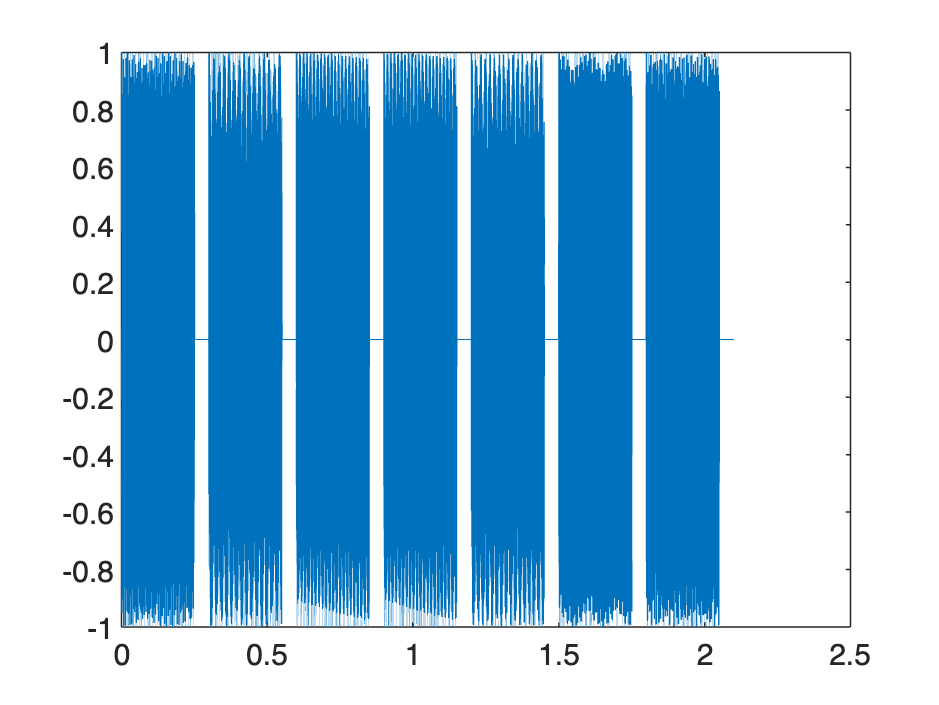

fs = 8000;
tone_len = 0.25;
quiet_len = 0.05;
tone_arr = [1, 2, 3, 3, 6, 9, 12];
n = 7;
dt = 1/fs;

x = ELEN133L_Lab2(tone_len, quiet_len, fs, tone_arr);

time = n * (tone_len + quiet_len);
t_vec = (0:((time * fs) - 1)) * dt;

plot(t_vec, x)

sound(x, fs)

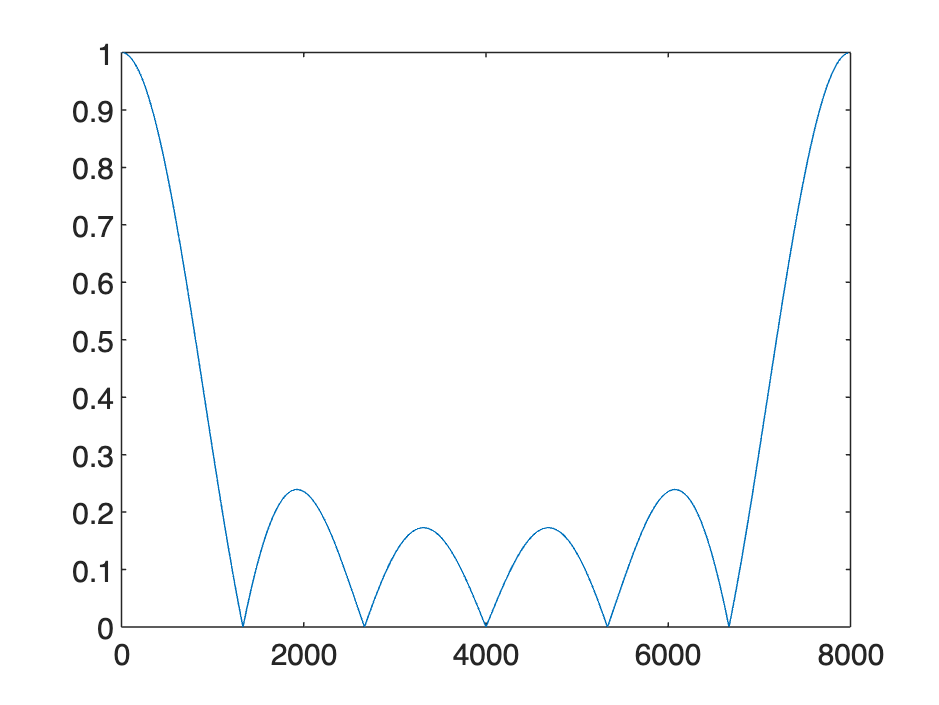

a = 1;
b = [1/6, 1/6, 1/6, 1/6, 1/6, 1/6];
[H, fv] = freqz(b, a, 'whole', 2048, fs);
plot(fv, abs(H));

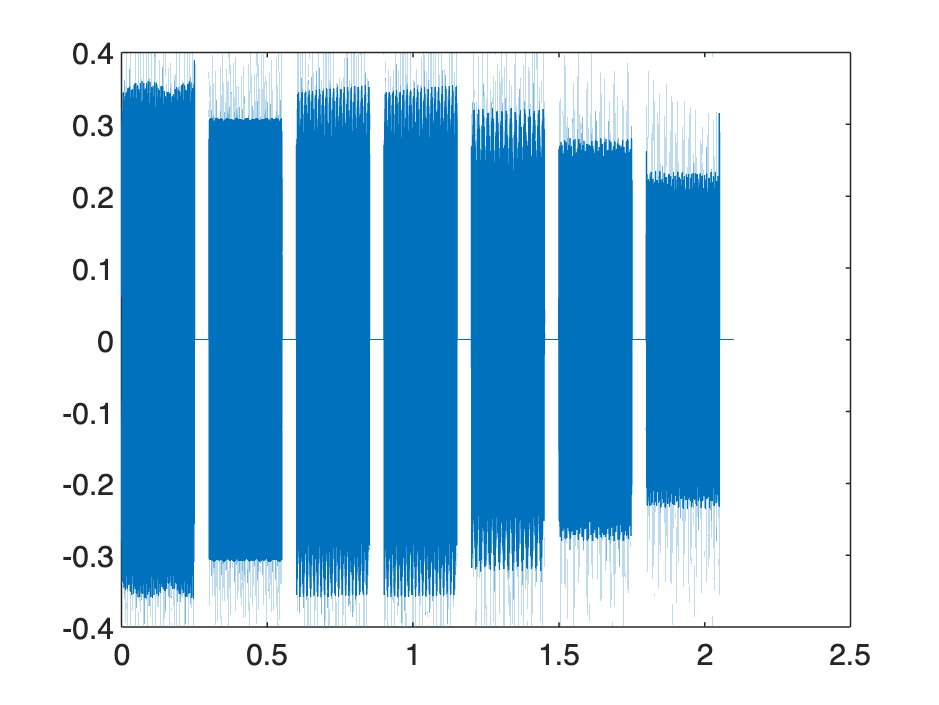

y = filter(b, a, x);
plot(t_vec, y);

sound(y, fs)